# Práctica No. 3

addpath("src");
import cuantizacionVectorial.*

## Generar puntos

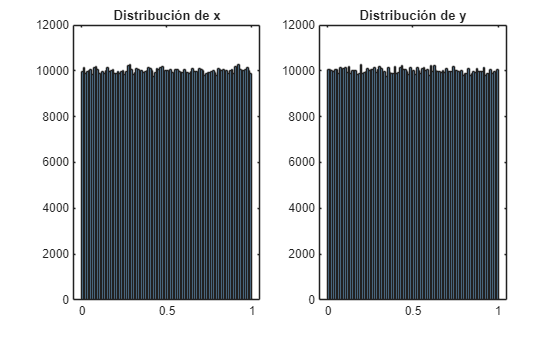

%Definir método y semilla para reproducibilidad.
rng(256,"twister");
%rand da una matriz del tamaño especificado con números al azar
%uniformemente distribuidos en el intervalo (0,1).
%x = columna 1, y = columna 2.
point = rand(1000000,2);

figure(1);
subplot(1,2,1);
histogram(point(:,1));
title("Distribución de x")
subplot(1,2,2);
histogram(point(:,2));
title("Distribución de y")

Las distribuciones individuales se ven uniformes, y no cambian al re-ejecutar la celda.

## Calculamos los cuantizadores para el número de regiones regiones solicitadas por los 3 métodos.

k = [1,2,4,8,16,64,256];
%LBG Fijo
cuantizadorLBG = cell(length(k),3);
for i = 1:length(k)
    f = @() cuantizacionVectorial.LBG(point,k(i),.0001,1000,"euclideana",[0 .0001]);
    [cuantizadorLBG{i,1}, cuantizadorLBG{i,2}] = f();
    cuantizadorLBG{i,3} = timeit(f);
    disp(k(i));
end

     1

     2

     4

     8

    16

    64



%LBGRandom
cuantizadorLBGRandom = cell(length(k),3);
for i = 1:length(k)
    f = @() cuantizacionVectorial.LBG(point,k(i),.0001,1000,"euclideana");
    [cuantizadorLBGRandom{i,1}, cuantizadorLBGRandom{i,2}] = f();
    cuantizadorLBGRandom{i,3} = timeit(f);
    disp(k(i));
end
%K-Medias

figure('Position',[0 0 1000 500]);
subplot(1,2,1);
cuantizacionVectorial.grafRegiones(point,cuantizador{1,1},"euclideana");
subplot(1,2,2)
cuantizacionVectorial.grafRegiones(point,cuantizador{2,1},"euclideana");

figure();
for i = 1:7
    subplot(4,2,i)
    plotRegion(point,Centroides{i,1});
end
function plotRegion(X,gamma)
    cmap = colormap("cool");
    indx = modperm(256,2);
    hold on;
    reg = calcRegiones(X,gamma);
    for i = 1:size(gamma,1)
        regX = X((reg == i),:);
        scatter(regX(:,1),regX(:,2),12,cmap(indx(i),:));
    end
    hold off;
end

function ind = modperm(n,m)
    ind2 = zeros(m,n/m);
    for i = 1:n
        ind2(mod(i,m) + 1,floor(i/m)+1) = i;
    end
    ind = reshape(ind2',[],1);
    ind = ind(ind ~= 0);
end

1.b LBG ... e aleatorio.